# AUTORePO structure

In this example, we present how the structure *AUTORePO* is organized when more than a single bifurcation diagram is saved in the `.auto` file. Specifically, we will illustrate, how to notice that one of your .auto file stores a 2P-BD, how to visualize a 2P-BD and how to change the variables along the x- and the y-axes for the visualization of a 1P-BD. Even in this example, the considered system is the Hodgkin Huxley model [1]. The ODEs of the system are the followings,

$\begin{array}{l}
c\dot{v} =I_0 +I_s \left(t\right)-I_{\textrm{Na}} \left(v,m,h\right)-I_K \left(v,n\right)-I_L \left(v\right),\\
\;\dot{m} =\alpha_m \left(v\right)\left(1-m\right)-\beta_m \left(v\right)m,\\
\;\dot{h} =\alpha_h \left(v\right)\left(1-h\right)-\beta_h \left(v\right)h,\\
\;\dot{n} =\alpha_{n\;} \left(v\right)\left(1-n\right)-\beta_n \left(v\right)n\ldotp 
\end{array}$   (1)

For more details reagarding this system, the reader should refer to [1]. The `.ode` file that we are going to use for this demo is a modified version of the one that you can find among the documentation of XPPAUT [2].

[1] Hodgkin AL, Huxley AF. *A quantitative description of membrane current and its application to conduction and excitation in nerve*. The Journal of Physiology, 1952.

[2] B Ermentrout. *Simulating, Analyzing, and Animating Dynamical Systems: A Guide to XPPAUT for Researchers and Students. *SIAM, 2002.

## ENVIROMENT SET-UP

We set up the environment by cleaning the workspace and the command window of the current MATLAB session and by closing all the opened figures. Then, we proceed by importing the folders and subfolders where the main XPPLORE functions are stored.

% ENVIRONMENT
clear all; close all; clc;

% IMPORT
addpath(genpath('../../Function_Visualization'))
addpath(genpath('../../Function_XPPAUT'))

## MODEL STRUCTURE

The first operation consists to read the model. For this reason, we use the function *Func_ReadModel *to collect the necessary information.

% MODEL
M = Func_ReadModel('hh.ode');

## AUTORePO

We load the file `hh.auto` by using the function *Func_ReadDiagram*. As it can be seen by executing the following chunk of code, the `.auto` file stores two bifurcation diagrams. These two are saved as fields of the structure `AR` as already presented in *DEMO1_HH_MDL* example. Their names are:

- `BD1_i0`: It is a 1P-BD computed by using as main bifurcation parameter the applied current ($I_0$, `i0`) in system (1).

- `BD2_i0_gk`: This is a 2P-BD where the main bifurcation parameter is `i0`, while the second bifurcation parameter is the potassium conductance `gk`.

This scenario is very common in the dynamical system daily basis practice. Specifically, scientists first compute a 1P-BD and then follow the most relevant bifurcations by changing a second parameter. Please keep in mind that, the integer number in the name of the bifurcation diagrams, hence 1 or 2 in the previous case, does not reflect the number of bifurcation parameters considered but it is just an incremental integer index. It will be clearer in the next demo file.

% AUTOREPO
AR = Func_ReadAutoRepo(M,'hh.auto');

AR:
    Parsing settings ...completed!
    Parsing hot parameters ...completed!
    Parsing branches & labelled points ...completed!
    Parsing Special Solutions...completed!

    Summary:
        1P-BD - Name: BD1_i0 - Main: i0
        2P-BD - Name: BD2_i0_gk - Main: i0 - Secondary: gk


## 1P-BD Visualization

We want to visualize the 1P-BD with its labelled points. Therefore, we use the functions *Func_VisualizeDiagram* and *Func_VisualizeLabPoints*. We remark that, if you do not specify the *VAR *optional field as an input parameter, the 1P-BD will be visualized on a plane where the main bifurcation parameter varies along the x-axis, while the first dynamical variable presented in the `.ode` model changes along the ordinate. Instead, in case of a 2P-BD, the second bifurcation parameter is presented along the y-direction. We haven't seen yet how to manipulate this field. For this reason, after recalling the basic visualization, we will present an example.

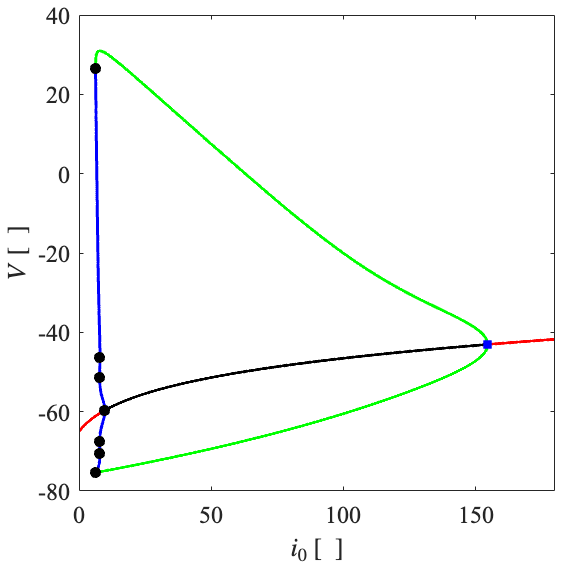

% VISUALIZATION
fig = figure();

Func_VisualizeDiagram(M,AR.BD1_i0)
Func_VisualizeLabPoints(M,AR.BD1_i0)

xlabel('$i_0$ [\ ]','interpreter','latex'), xlim([0  180])
ylabel('$V$ [\ ]','interpreter','latex')  , ylim([-80 40])

Func_FigStyle(fig)

Let us assume that, instead of visualizing the variable `V` along the y-axis, you prefer to visualize the variable `m`, that in this model represents the activation levels of the sodium channels. In this case, you have to specify manually both the variables to be visualized along the x- and y-axis. Therefore, the cell array `VAR` must be defined as `{'i0','m'}`.

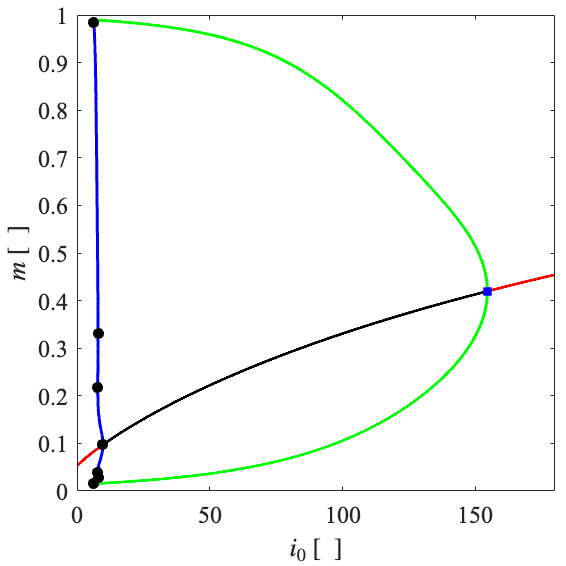

% VISUALIZATION
fig = figure();

Func_VisualizeDiagram(M,AR.BD1_i0,'VAR',{'i0','m'})
Func_VisualizeLabPoints(M,AR.BD1_i0,'VAR',{'i0','m'})

xlabel('$i_0$ [\ ]','interpreter','latex'), xlim([0 180])
ylabel('$m$ [\ ]','interpreter','latex')  , ylim([0 1])

Func_FigStyle(fig)

The VAR cell array can be at most of three-components. Their entries must be sorted to match `{'x','y','z'}`. If you specify only two variables, the visualization will be over the specified plane. In case of three-dimensional visualization, we reccomend to choose the right angle via the MATLAB command *view* otherwise the figure will appear as a two-dimensional plot when it opens up (you can always use the cursor and rotate the three-dimensional plot by directly interacting with the figure). We will see how to solve this issue in the next demo.

## 2P-BD Visualization

Now, we want to visualize the 2P-BD. For the 2P-BD visualization, we use the function *Func_VisualizeDiagram* only. Specifically, we pass as inputs the model and the BD to be visualized. By default, over the x- and the y-axes the parameters `i0` and `gk` will be visualized, respectively.

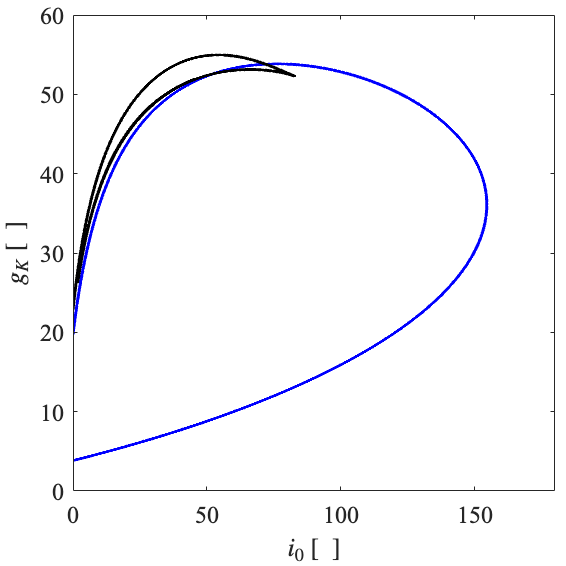

% VISUALIZATION
fig = figure();

Func_VisualizeDiagram(M,AR.BD2_i0_gk)

xlabel('$i_0$ [\ ]','interpreter','latex'), xlim([0 180])
ylabel('$g_K$ [\ ]','interpreter','latex'), ylim([0 60])

Func_FigStyle(fig)